medDatasetPath = fullfile('ds');

imds = imageDatastore(medDatasetPath, "IncludeSubfolders", true, "LabelSource", "foldernames");

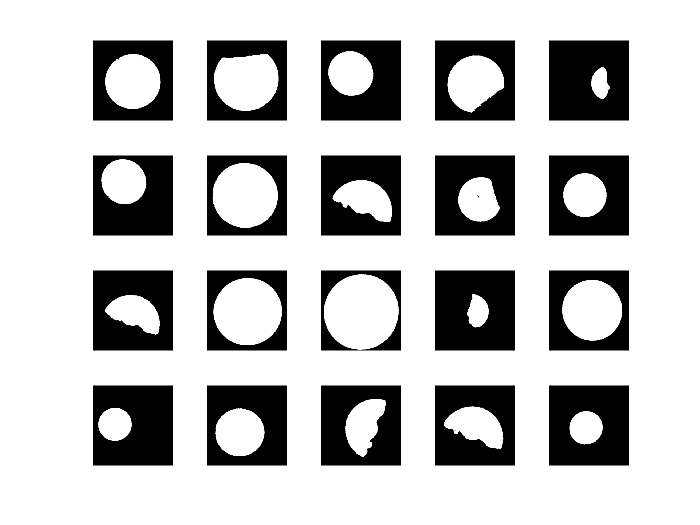

figure;
perm = randperm(60, 20);

for i = 1:20
    subplot(4, 5, i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

labelCount = 3×2 table
     Label      Count
    ________    _____

    Broken       34  
    NoDefect     34  
    Spot         34  


imgs = readimage(imds, 33);
size(imgs)

ans =    300   300


numTrainFiles = 32;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, "randomized");

layers = [
    imageInputLayer([300 300 1])
    
    convolution2dLayer(4, 32, "Padding", 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, "Stride", 2)
    
    convolution2dLayer(4, 64, "Padding", 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, "Stride", 2)
    
    convolution2dLayer(4, 128, "Padding", 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(3)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress', 'MiniBatchSize', 16);

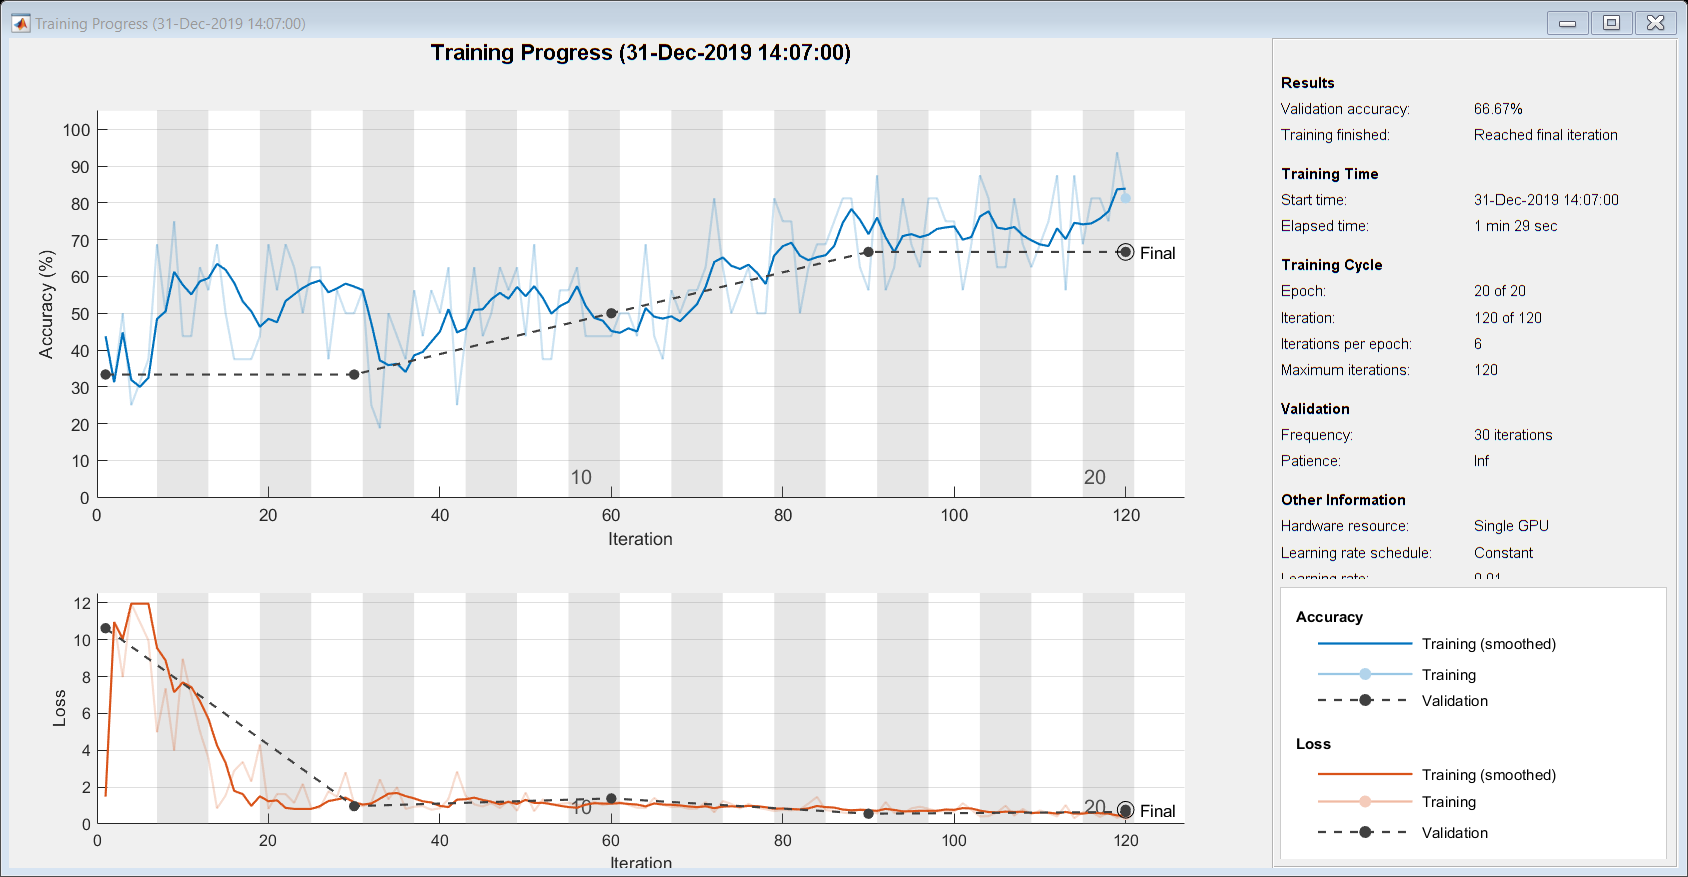

net = trainNetwork(imdsTrain,layers,options);                                        

[YPred, probs] = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.7778

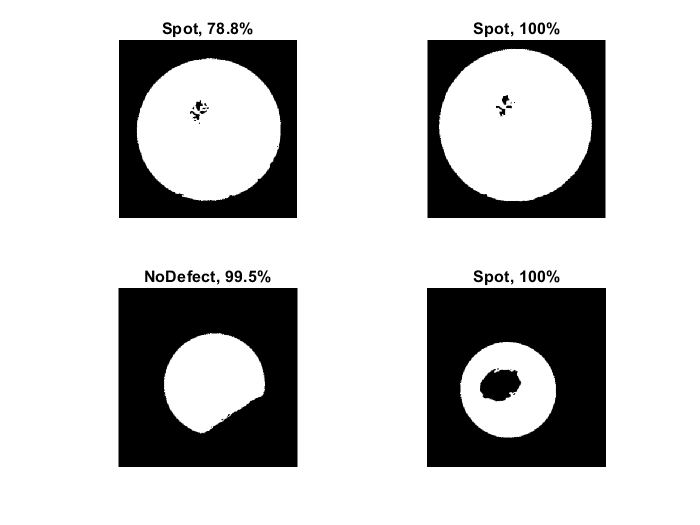

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

accuracy = 0.8333

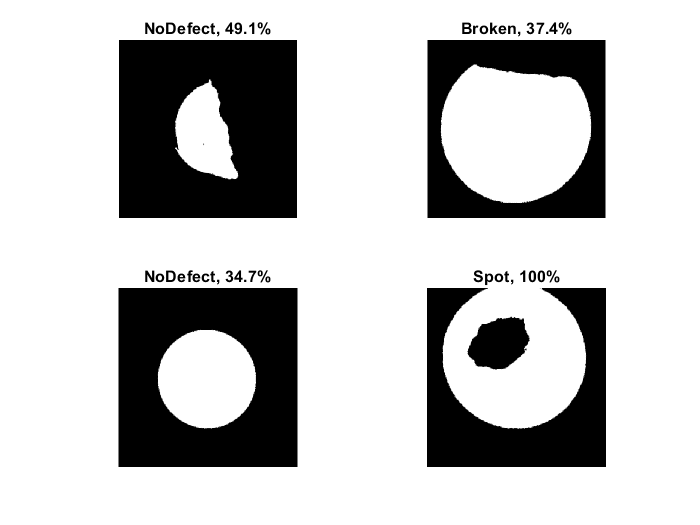

accuracy = 0.6667

accuracy = 0.6667